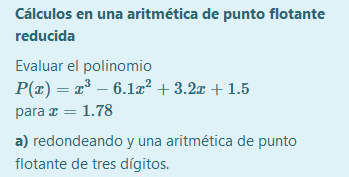

t=3;
x= 1.78;
P= x^3 - 6.1*x^2 + 3.2*x + 1.5;
arradonir(P,t)

ans = -6.4900


x1 = arradonir(arradonir(x^3,t) - arradonir(arradonir(6.1*x^2,t) + arradonir(arradonir(3.2*x,t) + arradonir(1.5,t),t),t),t)

x1 = -20.9000


abs(P-x1)/abs(P)

ans = 2.2196

Cap xifra significant correcte

x2= arradonir(arradonir(arradonir(arradonir(x,t)*x-6.1,t)*x + 3.2,t)*x+ 1.50,t)

x2 = -2.1000

abs(P-x1)/abs(P)

ans = 2.2196

Cap xifra significant correcta

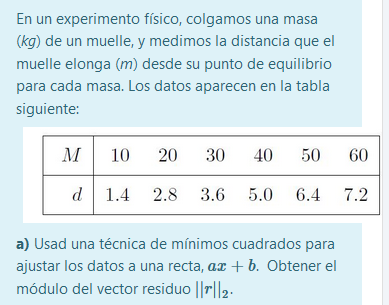

clear
x= [10 20 30 40 50 60];
y= [1.4 2.8 3.6 5.0 6.4 7.2]';

aux= ones(size(x,2),1);

A=[x',aux];
coeffpol= (A'*A)\(A'*y)

coeffpol =     0.1177
    0.2800


r=(polyval(coeffpol,x)-y);
norm(r,2)

ans = 12.0996


% APARTADO B


A2=[x'.^2,x',aux];
coeffpol2= (A2'*A2)\(A2'*y)

coeffpol2 =    -0.0001
    0.1252
    0.1800


r2=(polyval(coeffpol2,x)-y);
norm(r2,2)

ans = 12.0996

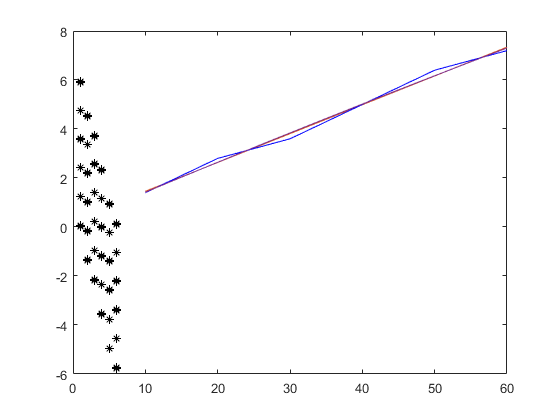


z=10:60;
pz= polyval(coeffpol,z);
plot(x,y,'-r',z,pz)

hold on

pz= polyval(coeffpol2,z);
plot(x,y,'-b',z,pz)
plot(r,'* black')
plot(r2,'* black')
hold off

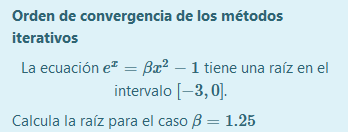

clear

f=@(t)1.5*t.^2-1-exp(t);

tol=0.5*10^-8;
nmax=100;

a=-3; b=0;
[table,res]=biseccion(f,a,b,tol,nmax)

table = 1×30 struct array with fields:
    a
    b
    fa
    fb
    alpha


res = -0.9602

RB=[];
for i=2:size(table,2)
    aux= -log10(2* abs(table(i).alpha - table(i-1).alpha)/abs(table(i).alpha));
    RB= [RB aux];
end

[table,res]=regulafalsi(f,a,b,tol,nmax)

table = 1×28 struct array with fields:
    a
    b
    Xn
    Fxn


res = -0.9602

RRF=[];
for i=2:size(table,2)
    aux= -log10(2* abs(table(i).Xn - table(i-1).Xn)/abs(table(i).Xn));
    RRF= [RRF aux];
end

[table,res]=secante(f,a,b,nmax,tol,tol)

table = 1×8 struct array with fields:
    Xn1
    absFx
    absX


res = -0.9602

RS=[];
for i=2:size(table,2)
    aux= -log10(2* abs(table(i).Xn1 - table(i-1).Xn1)/abs(table(i).Xn1));
    RS= [RS aux];
end

x0=-1.5;
df=@(t)3*t-exp(t);
[table,res]=newton(f,df,x0,nmax,tol,tol)

table = 1×5 struct array with fields:
    Xn
    absFx
    absX


res = -0.9602

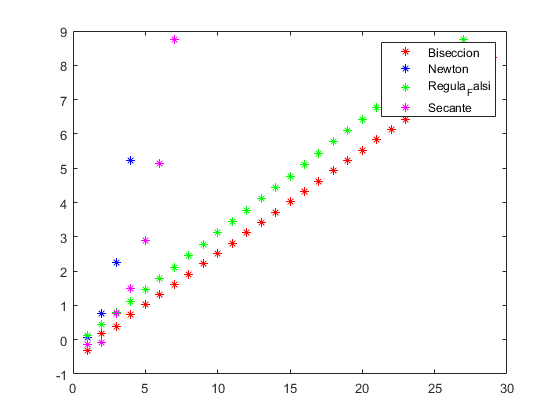

RN=[];
for i=2:size(table,2)
    aux= -log10(2* abs(table(i).Xn - table(i-1).Xn)/abs(table(i).Xn));
    RN= [RN aux];
end

plot(RB,'r*');
hold on

plot(RN,'b*')
plot(RRF,'g*')
plot(RS,'m*')
legend('Biseccion','Newton','Regula_Falsi','Secante');
hold off

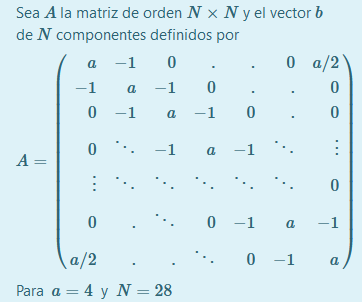

N=28;
A= zeros(N);
a= 4;
for i=1:N
    for j= 1:N
        val=0;
        
        if i == j
          val= a;
        elseif abs(i-j) == 1
            val=-1;
        end
        A(i,j)=val;
    end
end
A(1,N)= a/2;
A(N,1)= a/2;

b=ones(N,1);

[residu,it,xJ]=jacobi_res_it(A,b,50,0.5*10^-5);
xJ

xJ =     0.2383
    0.4299
    0.4812
    0.4950
    0.4987
    0.4996
    0.4999
    0.5000
    0.5000
    0.5000



[residu,it,xG]=gauss_res_it(A,b,50,0.5*10^-5);
xG

xG =     0.2383
    0.4299
    0.4812
    0.4950
    0.4987
    0.4996
    0.4999
    0.5000
    0.5000
    0.5000
